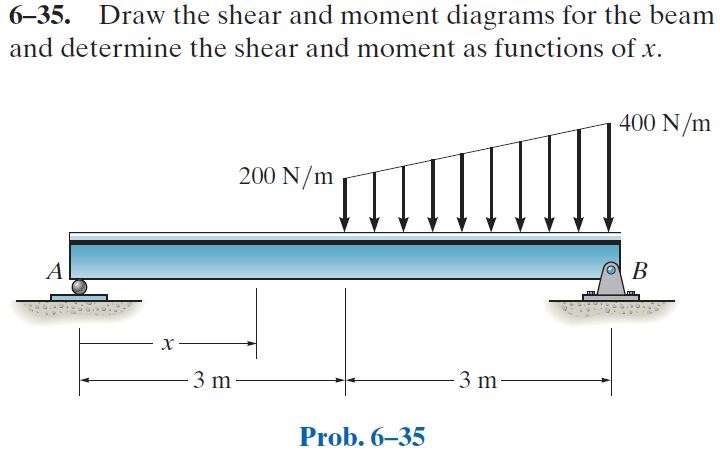

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-35P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-35P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# load data

w1 = findpoly(1, 'thru', [3*u.m -200*u.N/u.m], 'thru', [6*u.m -400*u.N/u.m]);

# beam

b = beam;
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('reaction', 'force', 'Rb', 6*u.m);
b = b.add('distributed', 'force', w1, [3 6]*u.m);
b.L = 6*u.m;

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} -\frac{5\,x\,\left(639\,m^{2}-20\,x^{2}\right)}{3\,\text{E}\,\text{I}}\,N & \text{ if }x\leq 3\,m\\ \frac{5\,\left(x-6\,m\right)\,\left(-x^{4}-6\,x^{3}\,m+114\,x^{2}\,m^{2}+144\,x\,m^{3}+162\,m^{4}\right)}{9\,\text{E}\,\text{I}}\,\frac{N}{m^{2}} & \text{ if }3\,m<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} -\frac{5\,\left(213\,m^{2}-20\,x^{2}\right)}{\text{E}\,\text{I}}\,N & \text{ if }x\leq 3\,m\\ -\frac{5\,\left(5\,x^{4}-450\,x^{2}\,m^{2}+1080\,x\,m^{3}+702\,m^{4}\right)}{9\,\text{E}\,\text{I}}\,\frac{N}{m^{2}} & \text{ if }3\,m<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} 200\,x\,N & \text{ if }x<3\,m\\ -\frac{100\,\left(x-6\,m\right)\,\left(x^{2}+6\,x\,m-9\,m^{2}\right)}{9}\,\frac{N}{m^{2}} & \text{ if }3\,m\leq x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} 200\,N & \text{ if }x<3\,m\\ \frac{100\,\left(15\,m^{2}-x^{2}\right)}{3}\,\frac{N}{m^{2}} & \text{ if }3\,m\leq x \end{array}\right.$$

w

$$w(x) = \left\{ \begin{array}{cl} 0 & \text{ if }x<3\,m\\ -\frac{200\,x}{3}\,\frac{N}{m^{2}} & \text{ if }3\,m\leq x \end{array}\right.$$

# reactions and hinges

ra

$$ra = \left(\begin{array}{cc} \mathrm{Ra} & 200\,N\\ \mathrm{Rb} & 700\,N \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagrams

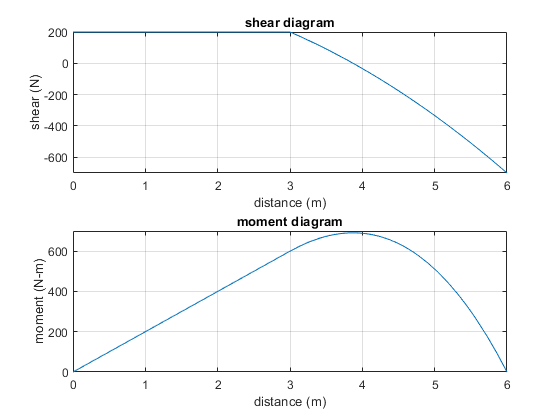

beam.shear_moment(m, v, [0 b.L], {'N' 'm'});

# clean up

addvar(y);
assume(old_assum);
clear old_assum;